% a clear MATLAB workspace is a clear mental workspace
close all; clear

## create data for the bar plot

% data sizes
m = 30; % rows
n =  6; % columns

% generate data
data = bsxfun(@times,30*randn(m,n),linspace(-1,1,n).^2);
data = bsxfun(@plus,data,(1:n).^2);

## show the bars

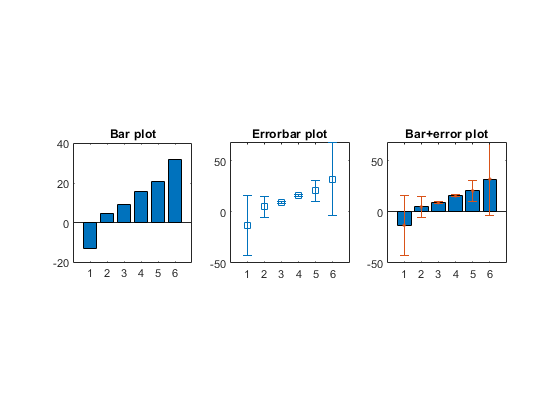

figure(1), clf
subplot(131)

% You can see how the bar increases from 1 to n (which is declared as 6 before)
bar(1:n,mean(data))
axis square, set(gca,'xlim',[0 n+1],'xtick',1:n)
title('Bar plot')

subplot(132)
errorbar(1:n,mean(data),std(data,[],1),'s')
axis square, set(gca,'xlim',[0 n+1],'xtick',1:n)
title('Errorbar plot')

subplot(133)
bar(1:n,mean(data))
hold on
errorbar(1:n,mean(data),std(data),'.')
axis square, set(gca,'xlim',[0 n+1],'xtick',1:n)
title('Bar+error plot')

## manually specify x-axis coordinates

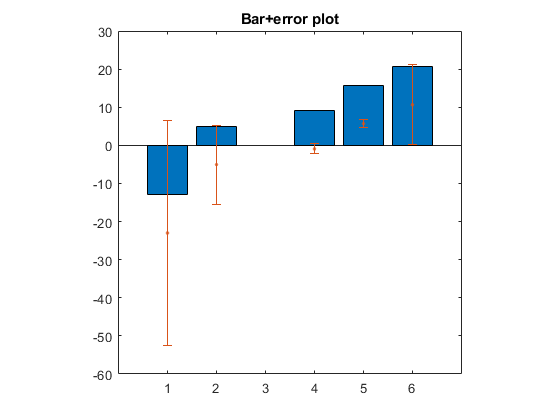

xcrossings = [ 1 2 4 5 6 9 ];

figure(2), clf

bar(xcrossings,mean(data))
hold on
errorbar(xcrossings,mean(data),std(data),'.') % Std returns the standard deviation
axis square, set(gca,'xlim',[0 n+1],'xtick',1:n)
title('Bar+error plot')

## note about bars from matrices

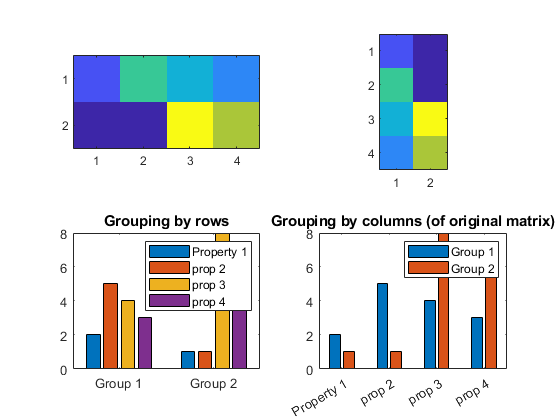

% data are groups (rows) X property (columns)
m = [2 5 4 3; 1 1 8 6];

figure(3), clf

% conceptualizing the data as <row> groups of <columns>
subplot(221)
imagesc(m), axis image
set(gca,'xtick',1:size(m,2),'ytick',1:size(m,1))

subplot(223)
bar(m)
set(gca,'xticklabel',{'Group 1';'Group 2'},'fontsize',10)
legend({'Property 1';'prop 2';'prop 3';'prop 4'})
title('Grouping by rows')



% now other orientation (property X group)
subplot(222)
imagesc(m'), axis image
set(gca,'xtick',1:size(m',2),'ytick',1:size(m',1))

subplot(224)
bar(m') % note the transpose
set(gca,'xticklabel',{'Property 1';'prop 2';'prop 3';'prop 4'},'fontsize',10)
legend({'Group 1';'Group 2'})
title('Grouping by columns (of original matrix)')

## done.